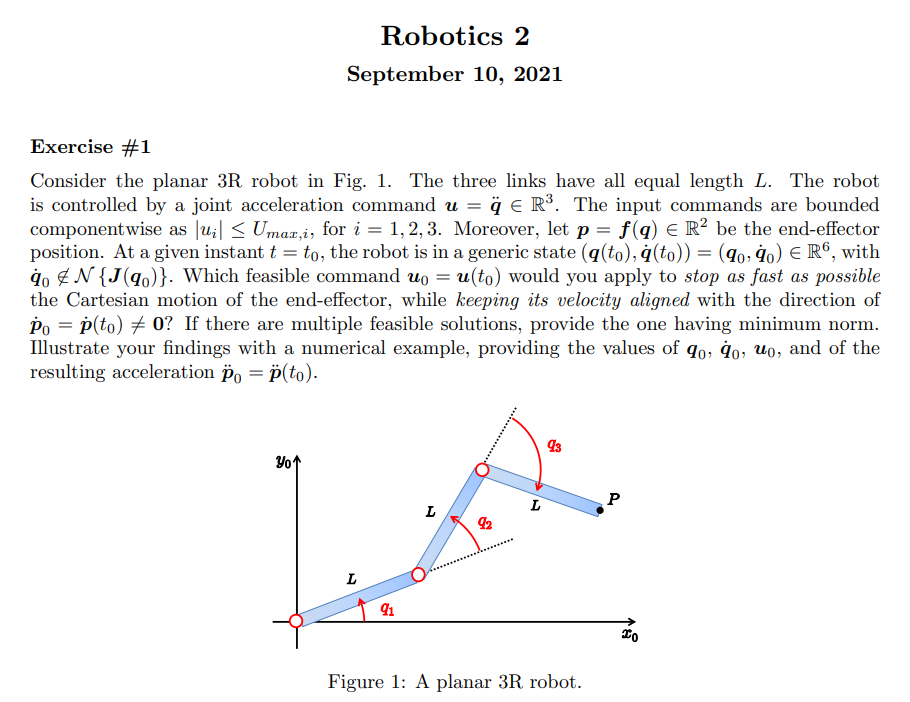

% % This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0,0,0];
n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
l_0 = sym('l','real');
l_=[l_0,l_0,l_0]' ;
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,-g0,0]';

R2Robot=['rrr';'xxx';sigmaD]

R2Robot = 3×3 char array
    'rrr'
    'xxx'
    '   '


z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;

z.q=q;
z.q_dot=q_dot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
         

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
z.opt_expr={[l],[l_]};
% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: {[3×1 sym]  [3×1 sym]}
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_re


[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: {[3×1 sym]  [3×1 sym]}
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_re

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{2}$$

d = 0

$$a = l_{3}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l+l^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \begin{array}{l} \left(\begin{array}{ccc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l+l^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} & \frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{2}+\frac{m_{3}\,\left({{\dot{q}}_{2}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l+l^{2}\right)+{{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,l^{2}+\sigma_{2}+2\,{\mathrm{dc}}_{3}\,l\,\cos\left(q_{3}\right)+\sigma_{1}\right)+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+2\,l^{2}+\sigma_{2}+4\,{\mathrm{dc}}_{3}\,l\,\cos\left(q_{3}\right)+\sigma_{1}\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l\,\cos\left(q_{3}\right)\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l\,\cos\left(q_{2}+q_{3}\right)+l\,\cos\left(q_{3}\right)\right)\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\mathrm{dc}}_{3}\,l\,\cos\left(q_{2}+q_{3}\right)\\ \sigma_{2}=2\,l^{2}\,\cos\left(q_{2}\right) \end{array}$$

$$f = \left(\begin{array}{c} l\,\cos\left(q_{1}+q_{2}\right)+l\,\cos\left(q_{1}\right)+l\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ l\,\sin\left(q_{1}+q_{2}\right)+l\,\sin\left(q_{1}\right)+l\,\sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

$$J = \begin{array}{l} \left(\begin{array}{ccc} -l\,\sin\left(q_{1}+q_{2}\right)-l\,\sin\left(q_{1}\right)-\sigma_{1} & -l\,\sin\left(q_{1}+q_{2}\right)-\sigma_{1} & -\sigma_{1}\\ l\,\cos\left(q_{1}+q_{2}\right)+l\,\cos\left(q_{1}\right)+\sigma_{2} & l\,\cos\left(q_{1}+q_{2}\right)+\sigma_{2} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=l\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$V = \left(\begin{array}{c} -l\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)-l\,\sin\left(q_{1}+q_{2}+q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)-l\,\sin\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ l\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)+l\,\cos\left(q_{1}+q_{2}+q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)+l\,\cos\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right) \end{array}\right)$$

PCVar = struct with fields:
         PTotali: [2×3 sym]
              Pc: [3×3 sym]
              vc: [3×3 sym]
     f_derivated: [1×1 struct]
           f_dot: [2×1 sym]
          f_ddot: [2×1 sym]
          f_tdot: [2×1 sym]
    pc_derivated: [1×1 struct]
         Pc_ddot: [3×3 sym]
               w: [3×3 sym]
               T: (m2*((dc2^2 + 2*cos(q_2)*dc2*l + l^2)*q_dot_1^2 + (2*dc2^2 + 2*l*cos(q_2)*dc2)*q_dot_1*q_dot_2 + dc2^2*q_dot_2^2))/2 + (I2*(q_dot_1 + q_dot_2)^2)/2 + (q_dot_1^2*(m1*dc1^2 + I1))/2 + (I3*(q_dot_1 + q_dot_2 + q_dot_3)^2)/2 + (m3*(q_do…
              Ti: [1×3 sym]
               M: [3×3 sym]


PC_EEShort = struct with fields:
              f: [2×1 sym]
              J: [2×3 sym]
    J_dot_short: [2×3 sym]
              V: [2×1 sym]
             Pc: [3×3 sym]
        Pc_ddot: []
        PTotali: [3×3 sym]


VarShortRobot = struct with fields:
    Pc: [3×3 sym]
    vc: [3×3 sym]
     w: [3×3 sym]
     T: (m3*(q_dot_1^2*(2*c2*l^2 + dc3^2 + 2*l^2 + 2*c3*dc3*l + 2*c2_3*dc3*l) + q_dot_2^2*(dc3^2 + 2*c3*dc3*l + l^2) + dc3^2*q_dot_3^2 + q_dot_1*q_dot_2*(2*c2*l^2 + 2*dc3^2 + 2*l^2 + 4*c3*dc3*l + 2*c2_3*dc3*l) + 2*dc3*q_dot_2*q_dot_3*(dc3 + c3*l) + 2…
    Ti: [1×3 sym]
     M: [3×3 sym]


PC_EE = struct with fields:
              f: [2×1 sym]
              J: [2×3 sym]
    J_derivated: [1×1 struct]
          J_dot: [2×3 sym]
         J_tdot: [2×3 sym]
           J_ps: [3×2 sym]
              V: [2×1 sym]


f

$$f = \left(\begin{array}{c} l\,\cos\left(q_{1}+q_{2}\right)+l\,\cos\left(q_{1}\right)+l\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ l\,\sin\left(q_{1}+q_{2}\right)+l\,\sin\left(q_{1}\right)+l\,\sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

collect(PCVar.f_dot,l_0)

$$ans = \left(\begin{array}{c} \left(-\sin\left(q_{1}+q_{2}+q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)-\sin\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)-{\dot{q}}_{1}\,\sin\left(q_{1}\right)\right)\,l\\ \left(\cos\left(q_{1}+q_{2}+q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)+\cos\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)+{\dot{q}}_{1}\,\cos\left(q_{1}\right)\right)\,l \end{array}\right)$$

collect(PC_EEShort.f,l_0)

$$ans = \left(\begin{array}{c} \left(c_{1}+c_{1,2}+c_{1,2,3}\right)\,l\\ \left(s_{1}+s_{1,2}+s_{1,2,3}\right)\,l \end{array}\right)$$

collect(PC_EEShort.J,l_0)

$$ans = \left(\begin{array}{ccc} \left(-s_{1}-s_{1,2}-s_{1,2,3}\right)\,l & \left(-s_{1,2}-s_{1,2,3}\right)\,l & \left(-s_{1,2,3}\right)\,l\\ \left(c_{1}+c_{1,2}+c_{1,2,3}\right)\,l & \left(c_{1,2}+c_{1,2,3}\right)\,l & c_{1,2,3}\,l \end{array}\right)$$

collect(f,l_0)

$$ans = \left(\begin{array}{c} \left(\cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)\,l\\ \left(\sin\left(q_{1}+q_{2}+q_{3}\right)+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)\,l \end{array}\right)$$

collect(J,l_0)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \left(-\sigma_{1}-\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right)\right)\,l & \left(-\sigma_{1}-\sin\left(q_{1}+q_{2}\right)\right)\,l & \left(-\sigma_{1}\right)\,l\\ \left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)\,l & \left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)\right)\,l & \sigma_{2}\,l \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

collect(PC_EEShort.J_dot_short,l_0)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \left(-c_{1,2}\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)-c_{1}\,{\dot{q}}_{1}-\sigma_{2}\right)\,l & \left(-c_{1,2}\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)-\sigma_{2}\right)\,l & \left(-\sigma_{2}\right)\,l\\ \left(-s_{1,2}\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)-{\dot{q}}_{1}\,s_{1}-\sigma_{1}\right)\,l & \left(-s_{1,2}\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)-\sigma_{1}\right)\,l & \left(-\sigma_{1}\right)\,l \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=s_{1,2,3}\,\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)\\ \sigma_{2}=c_{1,2,3}\,\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right) \end{array}$$

## defining Control output

lambda=sym('lambda','real')

$$lambda = \lambda$$

a_sym=sym('a','real')

$$a\_sym = a$$

b_sym=sym('b','real')

$$b\_sym = b$$

u_sym=lambda*a_sym+b_sym

$$u\_sym = b+a\,\lambda$$

## U_max definition

U_max_=[15,10,10]'*pi

U_max_ =    47.1239
   31.4159
   31.4159


q_=[0,pi/2,pi/2]'

q_ =          0
    1.5708
    1.5708


q_dot_=0.5*[pi,pi,0]'

q_dot_ =     1.5708
    1.5708
         0


l_=[1,1,1]'

l_ =      1
     1
     1


l_0_=1

l_0_ = 1

to_replace=[z.q;z.q_dot;z.l;l_0]

$$to\_replace = \left(\begin{array}{c} q_{1}\\ q_{2}\\ q_{3}\\ {\dot{q}}_{1}\\ {\dot{q}}_{2}\\ {\dot{q}}_{3}\\ l_{1}\\ l_{2}\\ l_{3}\\ l \end{array}\right)$$

to_replace_=[q_;q_dot_;l_;l_0_]

to_replace_ =          0
    1.5708
    1.5708
    1.5708
    1.5708
         0
    1.0000
    1.0000
    1.0000
    1.0000


## Replacing values

J0_=subs(J,to_replace,to_replace_)

$$J0\_ = \left(\begin{array}{ccc} -1 & -1 & 0\\ 0 & -1 & -1 \end{array}\right)$$

p0_dot_=J0_*q_dot_

$$p0\_dot\_ = \left(\begin{array}{c} -\pi \\ -\frac{\pi }{2} \end{array}\right)$$

f0_fot_=subs(PCVar.f_dot,to_replace,to_replace_)

$$f0\_fot\_ = \left(\begin{array}{c} -\pi \\ -\frac{\pi }{2} \end{array}\right)$$


J0_dot_=subs(PC_EE.J_dot,to_replace,to_replace_)

$$J0\_dot\_ = \left(\begin{array}{ccc} \frac{\pi }{2} & \pi & \pi \\ -\pi & -\pi & 0 \end{array}\right)$$

J0_pinv_=pinv(J0_)

$$J0\_pinv\_ = \left(\begin{array}{cc} -\frac{2}{3} & \frac{1}{3}\\ -\frac{1}{3} & -\frac{1}{3}\\ \frac{1}{3} & -\frac{2}{3} \end{array}\right)$$

h0_=J0_dot_*q_dot_

$$h0\_ = \left(\begin{array}{c} \frac{3\,\pi^{2}}{4}\\ -\pi^{2} \end{array}\right)$$

## getting u

a_=-J0_pinv_*J0_*q_dot_

$$a\_ = \left(\begin{array}{c} -\frac{\pi }{2}\\ -\frac{\pi }{2}\\ 0 \end{array}\right)$$

b_=-J0_pinv_*h0_

$$b\_ = \left(\begin{array}{c} \frac{5\,\pi^{2}}{6}\\ -\frac{\pi^{2}}{12}\\ -\frac{11\,\pi^{2}}{12} \end{array}\right)$$

a_=vpa(a_)

$$a\_ = \left(\begin{array}{c} -1.5707963267948966192313216916398\\ -1.5707963267948966192313216916398\\ 0 \end{array}\right)$$

b_=vpa(b_)

$$b\_ = \left(\begin{array}{c} 8.2246703342411321823620758332301\\ -0.82246703342411321823620758332301\\ -9.0471373676652454005982834165531 \end{array}\right)$$


% with complete computations it follows manually

a=sym('a',[z.n,1],'real');
b=sym('b',[z.n,1],'real');
U_max=sym('U_max',[z.n,1],'real');
sim_lp_vars.a=a;
sim_lp_vars.b=b;
sim_lp_vars.U_min=-U_max;
sim_lp_vars.U_max=U_max;

sim_lp_vars_.a=double(a_);
sim_lp_vars_.b=double(b_);
sim_lp_vars_.U_min=-U_max_;
sim_lp_vars_.U_max=U_max_;
% U_min=-U_max;
[lambda_i,lambda_i_,lambda_]=lp_problems_solver(sim_lp_vars,sim_lp_vars_)

$$inf\_sym = \mathrm{INFINITY}$$

$$lambda\_i\_ = \left(\begin{array}{ccc} 35.235987755982988775341451170535 & 19.476401224401701136601653467229 & 179769313486231570814527423731704356798070567525844996598917476803157260780028538760589558632766878171540458953514382464234321326889464182768467546703537516986049910576551282076245490090389328944075868508455133942304583236903222948165808559332123348274797826204144723168738177180919299881250404026184124858368 \end{array}\right)$$

$$lambda\_ = 19.476401224401701136601653467229$$

lambda_i_

$$lambda\_i\_ = \left(\begin{array}{ccc} 35.235987755982988775341451170535 & 19.476401224401701136601653467229 & 179769313486231570814527423731704356798070567525844996598917476803157260780028538760589558632766878171540458953514382464234321326889464182768467546703537516986049910576551282076245490090389328944075868508455133942304583236903222948165808559332123348274797826204144723168738177180919299881250404026184124858368 \end{array}\right)$$

lambda_

$$lambda\_ = 19.476401224401701136601653467229$$

lambda_i(1)

$$ans = \begin{array}{l} \left\{ \begin{array}{cl} -\mathrm{INFINITY} & \text{ if }U_{\mathrm{max1}}+b_{1}<0\wedge a_{1}\leq 0\\ \frac{U_{\mathrm{max1}}-b_{1}}{a_{1}} & \text{ if }U_{\mathrm{max1}}+b_{1}<0\wedge 0<a_{1}\\ \max\left(\left[\frac{U_{\mathrm{max1}}-b_{1}}{a_{1}},\sigma_{1}\right],\left[\right],2,\text{"omitnan"},\mathrm{symfalse}\right) & \text{ if }b_{1}<U_{\mathrm{max1}}\wedge 0\leq U_{\mathrm{max1}}+b_{1}\wedge a_{1}\neq 0\\ \mathrm{INFINITY} & \text{ if }b_{1}<U_{\mathrm{max1}}\wedge 0\leq U_{\mathrm{max1}}+b_{1}\wedge a_{1}=0\\ \sigma_{1} & \text{ if }U_{\mathrm{max1}}<b_{1}\wedge a_{1}<0\\ -\mathrm{INFINITY} & \text{ if }U_{\mathrm{max1}}<b_{1}\wedge 0\leq a_{1} \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=-\frac{U_{\mathrm{max1}}+b_{1}}{a_{1}} \end{array}$$

## Replacing valeus for U0

u=lambda*a+b

$$u = \left(\begin{array}{c} b_{1}+a_{1}\,\lambda \\ b_{2}+a_{2}\,\lambda \\ b_{3}+a_{3}\,\lambda \end{array}\right)$$

u_=subs(u,[a;b;lambda],[a_;b_;lambda_])

$$u\_ = \left(\begin{array}{c} -22.368789168232686999231512168234\\ -31.415926535897932399829795584787\\ -9.0471373676652454005982834165531 \end{array}\right)$$


p0_ddot_=-lambda_*p0_dot_

$$p0\_ddot\_ = \left(\begin{array}{c} 19.476401224401701136601653467229\,\pi \\ 9.7382006122008505683008267336144\,\pi \end{array}\right)$$

vpa(p0_ddot_)

$$ans = \left(\begin{array}{c} 61.186919004947638363187176002929\\ 30.593459502473819181593588001464 \end{array}\right)$$

## Exercise 2

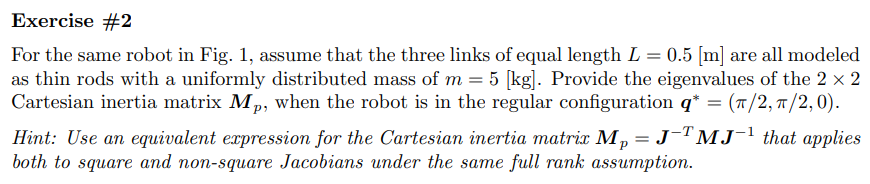

% % % close all
% % % % Lengths just to test
% % % d1_=10;
% % % d2_=10;
% % % a2_=10;
% % % % % De Luca's approach
% % %  links = [
% % %     Revolute('a', 0, 'alpha', -pi/2 ,'d', 1);
% % %     Revolute('a', a2_, 'alpha',0,'d', 0);
% % % %     Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
% % % %     Revolute('a', len1, 'alpha', 0 ,'d', 0);
% % %     ];
% % % % 
% % %  c600 = SerialLink(links);
% % %  c600.teach([0 0],'view','x');
% % % % c600.plot([0  pi/2 20 0],'view','x')
% % % clear

% 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% % alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,0,-g0]';

% R2Robot=['rrr';'xxx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% %             0       , z.l(2)  , 0   , q(2);]

% % 
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)
% % [Pc,vc,w,T,Ti,M] = getGenericPC2_xyz(z)

% Pc
% % vc
% % simplify(collect(expand(vc(:,2)'*vc(:,2)),z.q_dot(1)^2))
% % Ti(1)
% % Ti(2)
% M

## Replacing values

% % U_max=[15,10,10]'*pi
% % q_=[0,pi/2,pi/2]'
% % q_dot_=0.7*[pi,pi,0]'
% l_=[0.5,0.5,0.5]'
% dc_=l_/2
% m=5
% I_=(1/12)*m*(l_.^2)
% m_=[5,5,5]'
% % to_replace=[z.q;z.q_dot;z.l]
% % to_replace_=[q_;q_dot_;l_]
% 
% to_replace  =[z.l;z.dc;z.I;z.m]
% to_replace_ =[l_;dc_;I_;m_]

## Replacing values

% M_=subs(M,to_replace,to_replace_)
% J_=subs(J,to_replace,to_replace_)

## Replacing joints states

% q_=[pi/2,pi/2,0]'
% % q_dot_=0.7*[pi,pi,0]'
% 
% to_replace2=[z.q]
% to_replace2_=[q_]

% M2_=subs(M_,to_replace2,to_replace2_)
% J2_=subs(J_,to_replace2,to_replace2_)

## computation of M_p

% % M_p_=(J2_^(-1))'*M2_*(J2_^(-1))
% M_p_=pinv(J2_')*M2_*(pinv(J2_))
% M_p2_=pinv(J2_*pinv(M2_)*J2_')
% 
% % M_p3_=pinv(J2_')*pinv(J2_*pinv(M2_))
% vpa(eig(M_p2_))


## Exercise 3

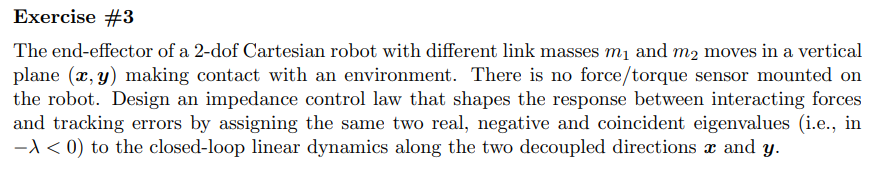

% 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [1,1];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% % alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

% R2Robot=['pp';'xy';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% %             0       , z.l(2)  , 0   , q(2);]

% % 
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

% [Msubs, dynamicParameters, aM] = getDynamicParameters(M,z.q,[])

% % Msubs
% % % 
% % 
% % % PC_EEShort.J
% % % PC_EEShort.f

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)

% [C,cac,Csubs] = getCs(M,z.q,z.q_dot)

% cac

% g_q
% U{:}

% % F_v=sym('F',[2,1],'real')
% % [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)

% % %complete model
% % Msubs*z.q_ddot+cac+F_v'*z.q_dot%=Tao
% Msubs*z.q_ddot+cac+g_q%=Tao

% M_inv=pinv(M)
% s=sym('s','real')
% lambda=sym('lambda','real')
% Dm=eye(n).* sym('D_m_',[n,1],'real')
% Km=eye(n).*sym('K_m_',[n,1],'real')
% 
% eig_mat= eye(n).*((s+lambda)^2)

% plant_s=eye(n).*s^2+M_inv*Dm*s+M_inv*Km

## solving equations

% solve(plant_s==eig_mat)